# Segmentación Semántica de imágenes térmicas de la estructura rocasa de una mina usando aprendizaje profundo 

**Descripción:** Se realizará la segmentación de imágenes térmicas mediante el uso de la Red Neuronal Convolucional ResNet-18. Este programa crea la red Deeplab v3 + con pesos inicializados desde una red Resnet-18. Se usan imágenes tomadas exclusivamente para este proyecto por el equipo de investigación encargado (INCIMMET / Grupo de Investigación Sistemas Aéreos No Tripulados - PUCP). Para su utilización en este programa las imágenes han sido pre-procesadas y etiquedas previamente.  Este ejemplo tiene como base un ejemplo proporcionado por el desarrollador del softwate MatLab [1]. 

**Autora:** Rocío Soto

clc; clear; close all; 

## Configuración

% Instalar resnet18 (Deep Learning Toolbox) y verificar
resnet18();

% Decargar una versión pre-entrenada de DeepLab v3+ para no esperar a que
% el entrenamiento se complete
pretrainedURL = 'https://www.mathworks.com/supportfiles/vision/data/deeplabv3plusResnet18CamVid.mat';
pretrainedFolder = fullfile(tempdir,'pretrainedNetwork');
pretrainedNetwork = fullfile(pretrainedFolder,'deeplabv3plusResnet18CamVid.mat'); 
if ~exist(pretrainedNetwork,'file')
    mkdir(pretrainedFolder);
    disp('Downloading pretrained network (58 MB)...');
    websave(pretrainedNetwork,pretrainedURL);
end 

## Cargar las imágenes y crear los datasets

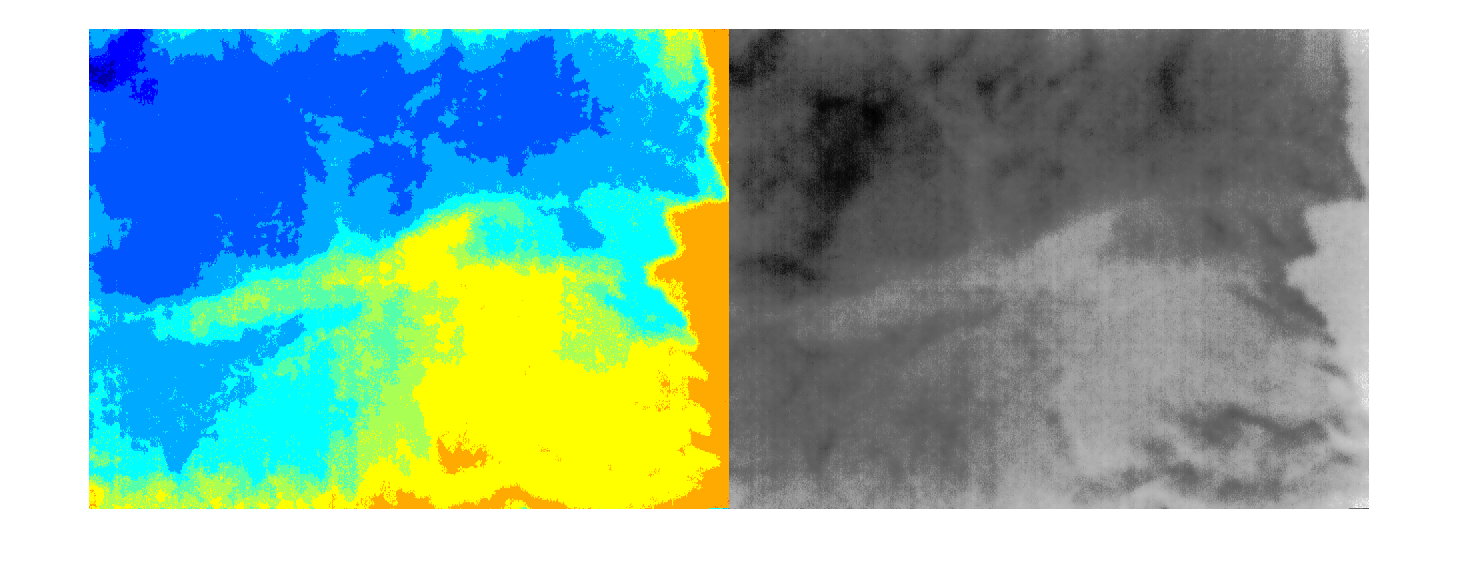

cd 'D:\INCIMMET\Rocío Soto\Imágenes';

% Dataset de las imágenes originales pre-procesadas
DataStore_Or = imageDatastore("Dataset_AdjThermalImg");
% Dataset de las imágenes etiquetadas
DataStore_Lbl = imageDatastore("Dataset_LabeledImg");

% Verificación de que el orden de las imágenes originales 
% corresponda al orden de las imágenes etiquetadas
I = readimage(DataStore_Lbl,50);
Or = readimage(DataStore_Or, 50);
figure(); imshowpair(I,Or,"montage")

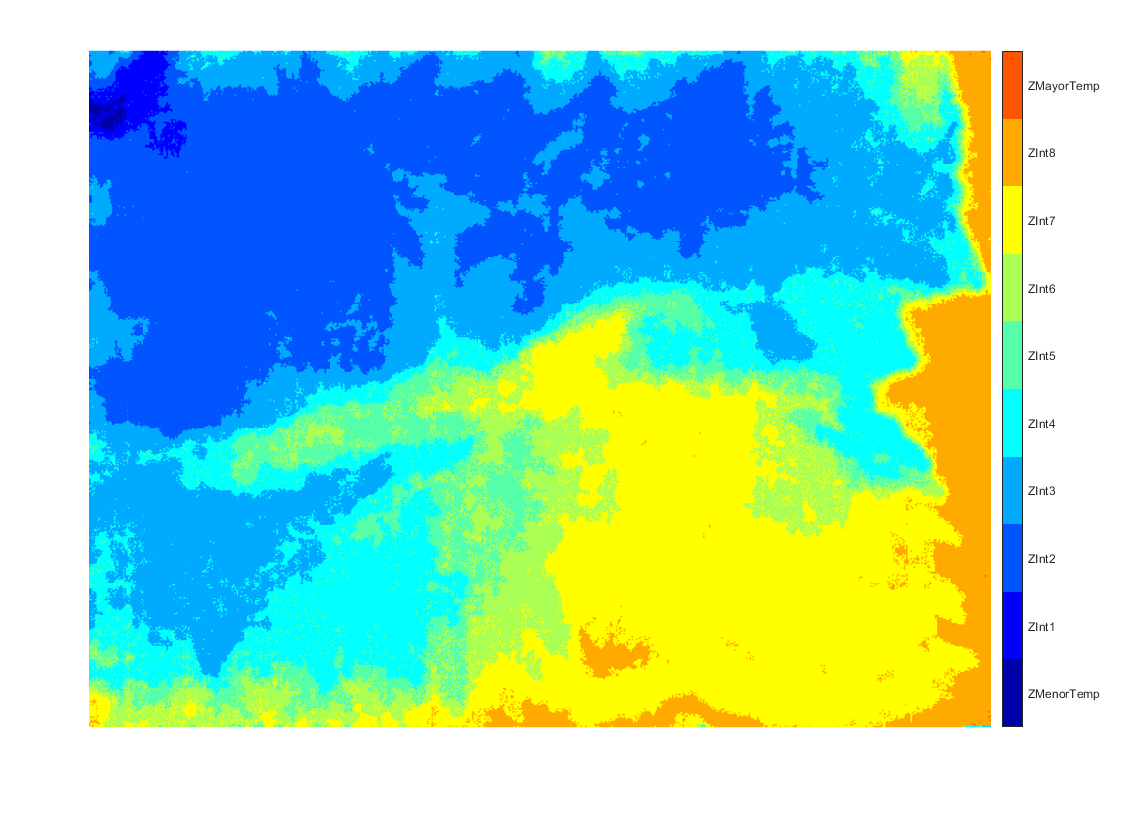


% Definición de las clases en las que se segmentarán las imágenes
classes = [
    "ZMenorTemp"
    "ZInt1"
    "ZInt2"
    "ZInt3"
    "ZInt4"
    "ZInt5"
    "ZInt6"
    "ZInt7"
    "ZInt8"
    "ZMayorTemp"
    ];
labelIDs = PixelLabelIDs();
labelDir = 'D:\INCIMMET\Rocío Soto\Imágenes\Dataset_LabeledImg';

% Creación del dataset de imagenes etiquetadas teniendo en cuenta las
% clases
pxds = pixelLabelDatastore(labelDir,classes,labelIDs);

% Verificación: superponer una imagen etiquetada sobre una original 
% teniendo en cuenta las clses definidas
C = readimage(pxds,50);
cmap = ThermalColorMap();
B = labeloverlay(I,C,'ColorMap',cmap);
imshow(B)
pixelLabelColorbar(cmap,classes);

## Análisis de las estadísticas de los datasets

% Cantidad de pixeles por cada clase definida
tbl = countEachLabel(pxds)

tbl = 10×3 table
         Name         PixelCount    ImagePixelCount
    ______________    __________    _______________

    {'ZMenorTemp'}    1.8844e+07      1.0022e+08   
    {'ZInt1'     }    2.8664e+07      1.6105e+08   
    {'ZInt2'     }    2.7018e+07      1.7418e+08   
    {'ZInt3'     }    1.8228e+07      1.7556e+08   
    {'ZInt4'     }    1.6913e+07      1.7556e+08   
    {'ZInt5'     }    9.3568e+06       1.728e+08   
    {'ZInt6'     }    5.6797e+06      1.6796e+08   
    {'ZInt7'     }    4.7134e+06      1.7004e+08   
    {'ZInt8'     }    1.3886e+06      1.5483e+08   
    {'ZMayorTemp'}    4.2349e+05      1.0368e+08   


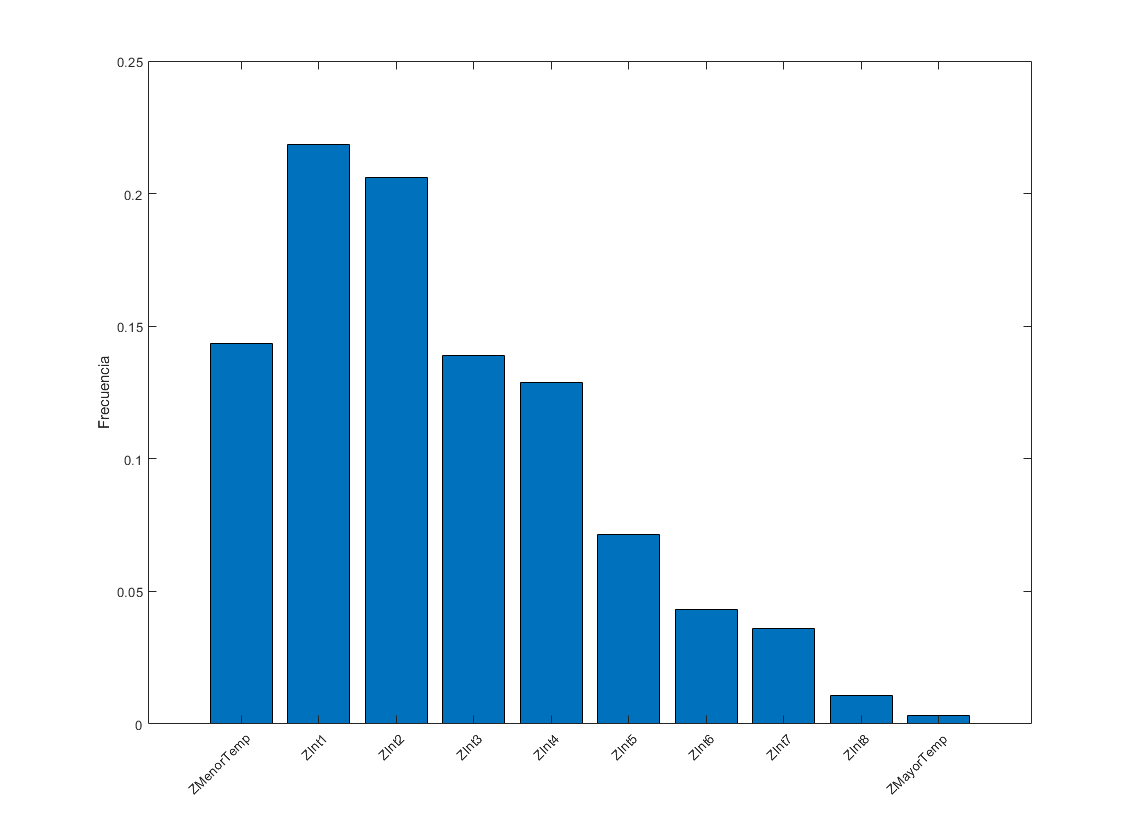

% Visualización del recuento de píxeles por clase
frequency = tbl.PixelCount/sum(tbl.PixelCount);
bar(1:numel(classes),frequency)
xticks(1:numel(classes)) 
xticklabels(tbl.Name)
xtickangle(45)
ylabel('Frecuencia')

## Preparación para hacer entrenamiento

% División de las imágenes en grupos para entrenamiento, 
% validación y pruebas
[imdsTrain, imdsVal, imdsTest, pxdsTrain, pxdsVal, pxdsTest] = partitionData(DataStore_Or,pxds);

%Verificación: 60%-entrenamiento, 20%-validación, 20%-pruebas
numTrainingImages = numel(imdsTrain.Files)

numTrainingImages = 153

numValImages = numel(imdsVal.Files)

numValImages = 51

numTestingImages = numel(imdsTest.Files)

numTestingImages = 51


% Especificar el tamño de imagen de la red.
imageSize = [720 960 3];

% Especificar el número de clases
numClasses = numel(classes);

% Crear la red
lgraph = deeplabv3plusLayers(imageSize, numClasses, "resnet18");

% Para mejorar el entrenamiento, utilizar 
% la ponderación de clases para equilibrar las clases
imageFreq = tbl.PixelCount ./ tbl.ImagePixelCount;
classWeights = median(imageFreq) ./ imageFreq;
pxLayer = pixelClassificationLayer('Name','labels','Classes',tbl.Name,'ClassWeights',classWeights);
lgraph = replaceLayer(lgraph,"classification",pxLayer);

### Seleccionar opciones de entrenamiento

% Definición de los datos de validación
dsVal = combine(imdsVal,pxdsVal);

% Definición de los datos de validación 
options = trainingOptions('sgdm', ...
    'LearnRateSchedule','piecewise',...
    'LearnRateDropPeriod',10,...
    'LearnRateDropFactor',0.3,...
    'Momentum',0.9, ...
    'InitialLearnRate',1e-3, ...
    'L2Regularization',0.005, ...
    'ValidationData',dsVal,...
    'MaxEpochs',30, ...  
    'MiniBatchSize',6, ...
    'Shuffle','every-epoch', ...
    'CheckpointPath', tempdir, ...
    'VerboseFrequency',2,...
    'Plots','training-progress',...
    'ValidationPatience', 4);

### Aumento de datos

Para mejorar la precisión de la red al transformar aleatoriamente los datos originales durante el entrenamiento.

dsTrain = combine(imdsTrain, pxdsTrain);

xTrans = [-10 10];
yTrans = [-10 10];
sTrain = transform(dsTrain, @(data)augmentImageAndLabel(data,xTrans,yTrans));

## Inicio del entrenamiento

Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:26 |        6.03% |        7.27% |       2.6019 |       2.5425 |          0.0010 |
|       1 |           2 |       00:00:30 |        7.62% |              |       2.5820 |              |          0.0010 |
|       1 |           4 |       00:00:35 |       11.03% |              |       2.2075 |              |          0.0010 |
|       1 |           6 |       00:00:39 |       13.22% |              |       2.2663 |   

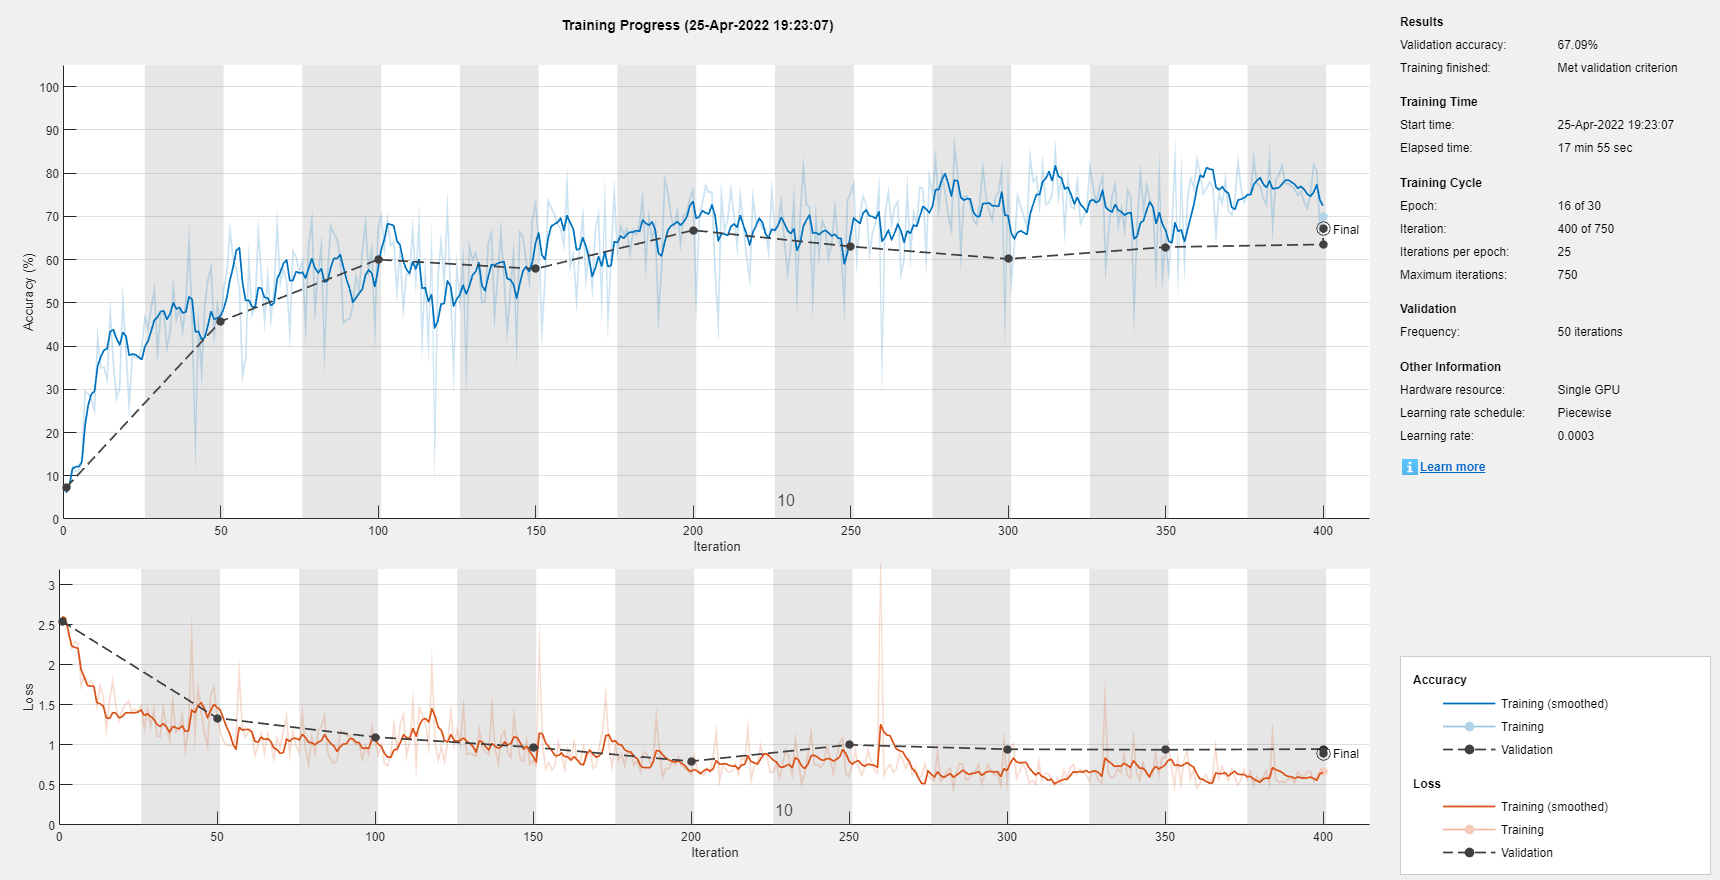

doTraining = true;
if doTraining    
    [net, info] = trainNetwork(dsTrain,lgraph,options);
else
    data = load(pretrainedNetwork); 
    net = data.net;
end

## Prueba de la Red en una sola imagen

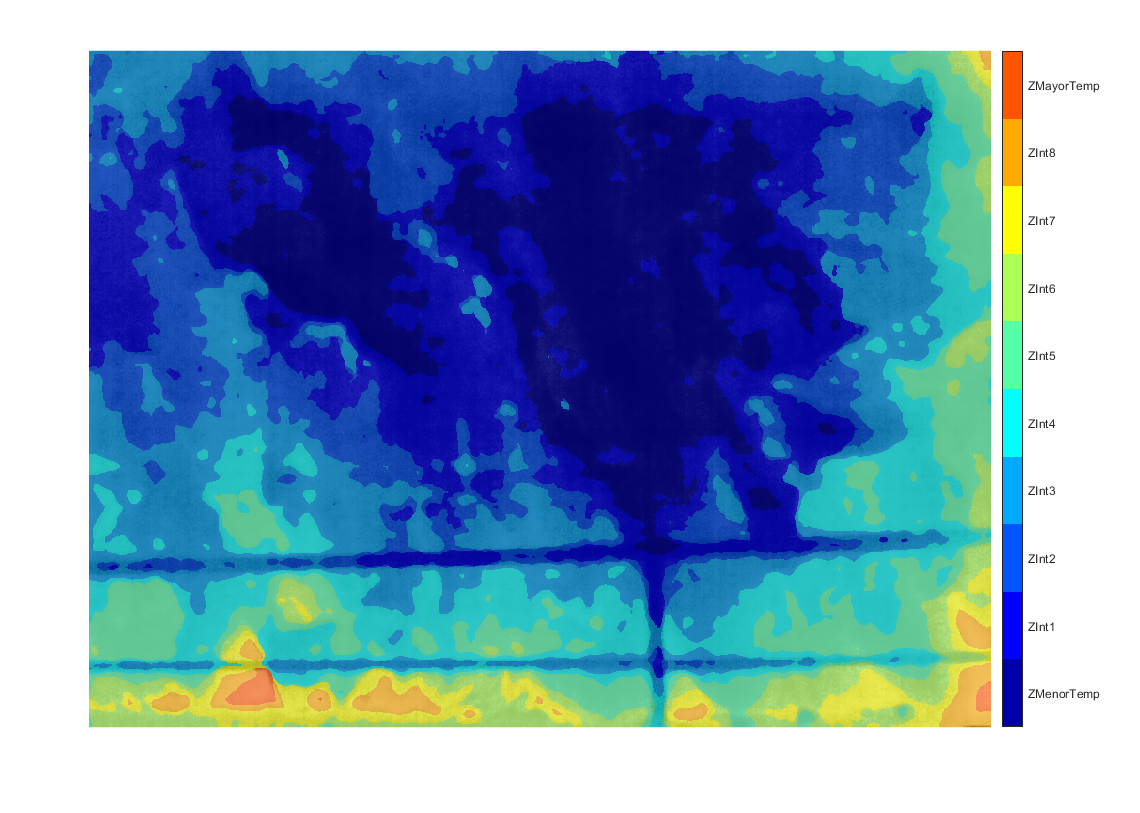

I = readimage(imdsTest,5);
C = semanticseg(I, net);
B = labeloverlay(I,C,'Colormap',cmap,'Transparency',0.4);
imshow(B)
pixelLabelColorbar(cmap, classes);

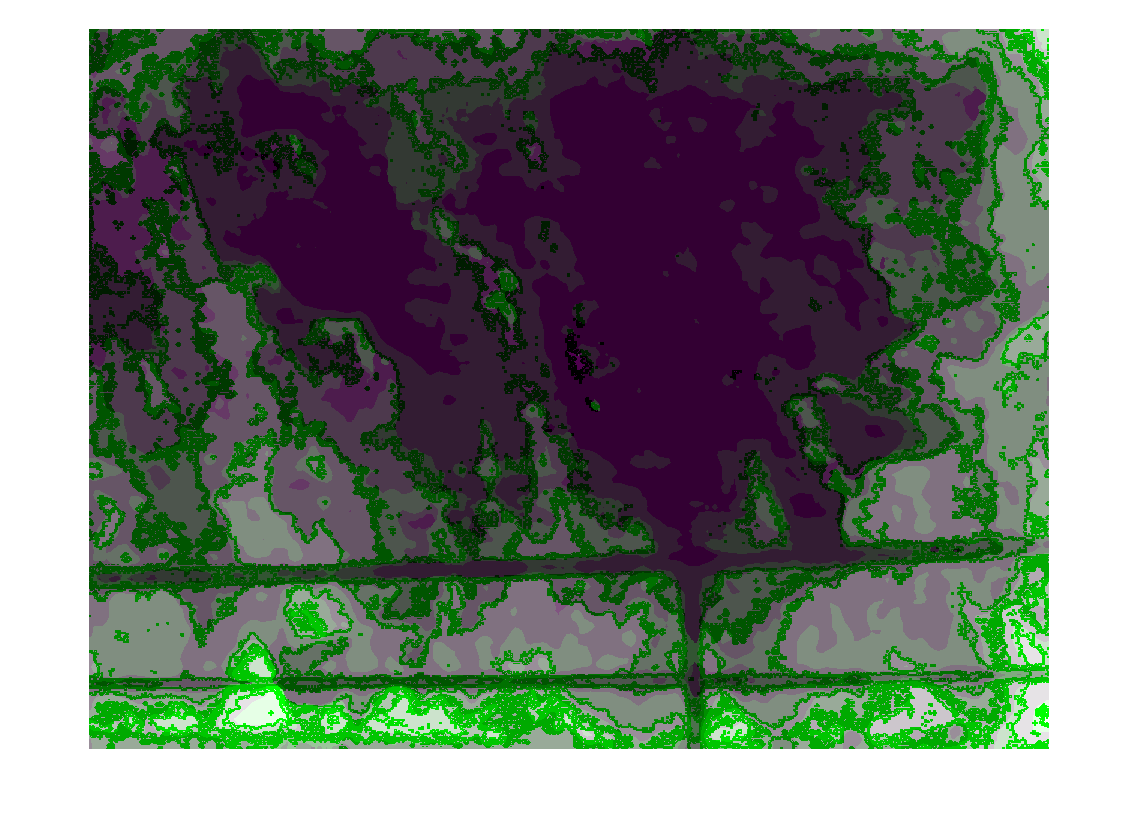


expectedResult = readimage(pxdsTest,5);
actual = uint8(C);
expected = uint8(expectedResult);
imshowpair(actual, expected)


% Métrica para medir el grado de similitud entre la segmentación
% realizada por la red y la segmentación deseada por cada clase (IoU)
iou = jaccard(C,expectedResult);
table(classes,iou)

ans = 10×2 table
      classes         iou   
    ____________    ________

    "ZMenorTemp"           0
    "ZInt1"          0.37167
    "ZInt2"          0.29077
    "ZInt3"          0.27153
    "ZInt4"          0.33868
    "ZInt5"         0.071477
    "ZInt6"         0.038657
    "ZInt7"          0.14108
    "ZInt8"          0.16633
    "ZMayorTemp"    0.011403


## Evaluación de todos los resultados obtenidos por la Red Entrenada

pxdsResults = semanticseg(imdsTest,net, ...
    'MiniBatchSize',4, ...
    'WriteLocation',tempdir, ...
    'Verbose',false);

metrics = evaluateSemanticSegmentation(pxdsResults,pxdsTest,'Verbose',false);
metrics.DataSetMetrics

ans = 1×5 table
    GlobalAccuracy    MeanAccuracy    MeanIoU    WeightedIoU    MeanBFScore
    ______________    ____________    _______    ___________    ___________

       0.67185          0.60211       0.4586       0.51055        0.72385  


metrics.ClassMetrics

ans = 10×3 table
                  Accuracy      IoU      MeanBFScore
                  ________    _______    ___________

    ZMenorTemp    0.80436      0.6903      0.49625  
    ZInt1         0.57348     0.45657      0.57732  
    ZInt2         0.66585     0.47913      0.65894  
    ZInt3         0.78014     0.46154      0.79002  
    ZInt4         0.65697     0.55583      0.86035  
    ZInt5         0.72688     0.51766      0.83529  
    ZInt6         0.66111     0.47946      0.80548  
    ZInt7         0.56341      0.4466      0.75674  
    ZInt8         0.31421     0.24766       0.6731  
    ZMayorTemp    0.27472     0.25125      0.59982  


function labelIDs = PixelLabelIDs()
% Devuelve los Ids de etiqueta que corresponden a cada clase
%
% La imagenes etiquetadas tienen 4 clases.Con esta función se agrupan estas clases en 3

labelIDs = { ...
    
    % "Zona de menor temeperatura"
    [
    000 000 170; ... 
    ]
    % "Zona intermedia 1"
    [
    000 000 255; ... 
    ]
    % "Zona intermedia 2"
    [
    000 085 255; ... 
    ]
    % "Zona intermedia 3"
    [
    000 170 255; ...
    ]
     % "Zona intermedia 4"
    [
    000 255 255; ... 
    ]
     % "Zona intermedia 5"
    [
    085 255 170; ... 
    ]
     % "Zona intermedia 6"
    [
    170 255 085; ... 
    ]
     % "Zona intermedia 7"
    [
    255 255 000; ... 
    ]
     % "Zona intermedia 8"
    [
    255 170 000; ... 
    ]
     % "Zona de mayor temeperatura"
    [
    255 085 000; ... 
    ]

    };
end


function cmap = ThermalColorMap()
% Define el colormap utilizado en la imagenes etiquetadas.

cmap = [
    000 000 170 % "Zona de menor temperatura"
    000 000 255 % "Zona Intermedia 1"
    000 085 255 % "Zona Intermedia 2"
    000 170 255 % "Zona Intermedia 3"
    000 255 255 % "Zona Intermedia 4"
    085 255 170 % "Zona Intermedia 5"
    170 255 085 % "Zona Intermedia 6"
    255 255 000 % "Zona Intermedia 7"
    255 170 000 % "Zona Intermedia 8"
    255 085 000 % "Zona de mayor temperatura"
    ];
cmap = cmap ./ 255;
end

function pixelLabelColorbar(cmap, classNames)
% Agrega una barra de colores al eje actual. La barra de colores 
% está formateada para mostrar los nombres de las clases con el color.

colormap(gca,cmap)

c = colorbar('peer', gca);

c.TickLabels = classNames;
numClasses = size(cmap,1);
c.Ticks = 1/(numClasses*2):1/numClasses:1;
c.TickLength = 0;
end

function [imdsTrain, imdsVal, imdsTest, pxdsTrain, pxdsVal, pxdsTest] = partitionData(imds,pxds)
% Divide los datos de los datsets seleccionando aleatoriamente 
% el 60% de los datos para el entrenamiento. El resto se usa para pruebas.
    
% Establecer el estado aleatorio inicial
rng(0); 
numFiles = numel(imds.Files);
shuffledIndices = randperm(numFiles);

% Usar el 60 % para el entrenamiento
numTrain = round(0.60 * numFiles);
trainingIdx = shuffledIndices(1:numTrain);

% Usar el 20% para la validación
numVal = round(0.20 * numFiles);
valIdx = shuffledIndices(numTrain+1:numTrain+numVal);

% Usar el resto para las pruebas
testIdx = shuffledIndices(numTrain+numVal+1:end);

% Crear datastores de imagenes para entrenamiento y pruebas.
trainingImages = imds.Files(trainingIdx);
valImages = imds.Files(valIdx);
testImages = imds.Files(testIdx);

imdsTrain = imageDatastore(trainingImages);
imdsVal = imageDatastore(valImages);
imdsTest = imageDatastore(testImages);

% Extraer información de los IDs de etiqueta y clase.
classes = pxds.ClassNames;
labelIDs = PixelLabelIDs();

% Crear datastores de etiquetas para entrenamiento y pruebas.
trainingLabels = pxds.Files(trainingIdx);
valLabels = pxds.Files(valIdx);
testLabels = pxds.Files(testIdx);

pxdsTrain = pixelLabelDatastore(trainingLabels, classes, labelIDs);
pxdsVal = pixelLabelDatastore(valLabels, classes, labelIDs);
pxdsTest = pixelLabelDatastore(testLabels, classes, labelIDs);
end


function data = augmentImageAndLabel(data, xTrans, yTrans)
% Aumenta las imágenes y las imágenes etiquetadas mediante la reflexión 
% y la traducción aleatorias.

    for i = 1:size(data,1)
        
        tform = randomAffine2d(...
            'XReflection',true,...
            'XTranslation', xTrans, ...
            'YTranslation', yTrans);
        
        rout = affineOutputView(size(data{i,1}), tform, 'BoundsStyle', 'centerOutput');
        
        data{i,1} = imwarp(data{i,1}, tform, 'OutputView', rout);
        data{i,2} = imwarp(data{i,2}, tform, 'OutputView', rout);
        
    end
end